nvars = 4;
m = 10;
fun = @(x) shekel_func(x, m);

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


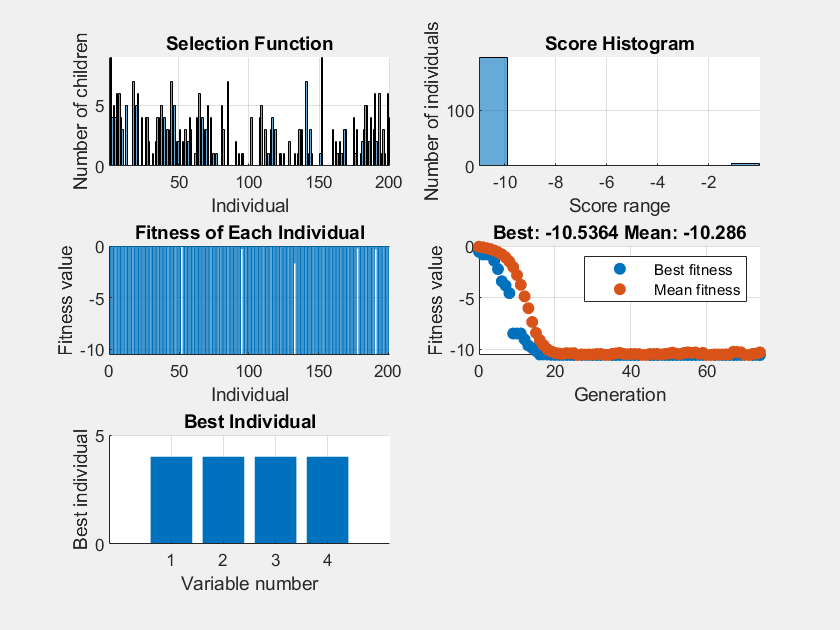

% Set nondefault solver options
options = optimoptions("ga","PopulationSize",200,"MutationFcn",...
    "mutationuniform","CrossoverFcn","crossoverlaplace","SelectionFcn",...
    "selectiontournament","FitnessScalingFcn","fitscalingtop","PlotFcn",...
    ["gaplotselection","gaplotscorediversity","gaplotscores","gaplotbestf",...
    "gaplotbestindiv"]);

% Solve
[solution,objectiveValue] = ga(fun,nvars,[],[],[],[],[],[],[],[],options);


% Clear variables
clearvars options